graphs = init_population3(15, 150);
graphs

graphs = 1×150 cell 数组
    {15×15 double}    {15×15 double}    {15×15 double}    {15×15 double}    {15×15 double}    {15×15 double}    {15×15 double}    {15×15 double}    {15×15 double}    {15×15 double}    {15×15 double}    {15×15 double}    {15×15 double}    {15×15 double}    {15×15 double}    {15×15 double}    {15×15 double}    {15×15 double}    {15×15 double}    {15×15 double}    {15×15 double}    {15×15 double}    {15×15 double}    {15×15 double}    {15×15 double}    {15×15 double}    {15×15 double}    {15×15 double}    {15×15 double}    {15×15 double}    {15×15 double}    {15×15 double}    {15×15 double}    {15×15 double}    {15×15 double}    {15×15 double}    {15×15 double}    {15×15 double}    {15×15 double}    {15×15 double}    {15×15 double}    {15×15 double}    {15×15 double}    {15×15 double}    {15×15 double}    {15×15 double}    {15×15 double}    {15×15 double}    {15×15 double}    {15×15 double}    {15×15 double}    {15×15 double}    {15×15 double}    {15×15 double}    {

[allFronts, ~] = non_dominated_sorting(graphs);
multiFitValues = multi_obj_fitness(graphs);
f1 = ones(1, 150)./multiFitValues{1};
f2 = ones(1, 150)./multiFitValues{2};
f3 = ones(1, 150)./multiFitValues{3};
set(gcf,'Position',[100 100 260 220]);

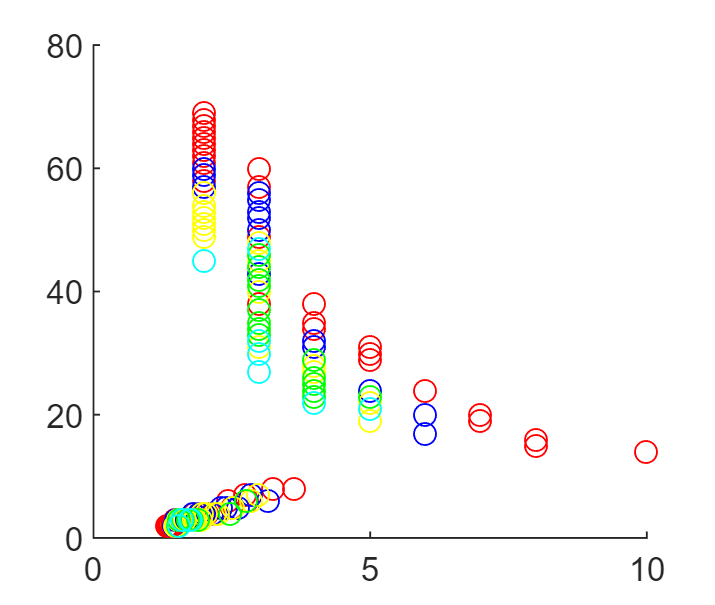

hold on
plot(f1(allFronts(1).front), f2(allFronts(1).front), 'ro');
plot(f1(allFronts(2).front), f2(allFronts(2).front), 'bo');
plot(f1(allFronts(3).front), f2(allFronts(3).front), 'yo');
plot(f1(allFronts(4).front), f2(allFronts(4).front), 'go');
plot(f1(allFronts(5).front), f2(allFronts(5).front), 'co');
hold off

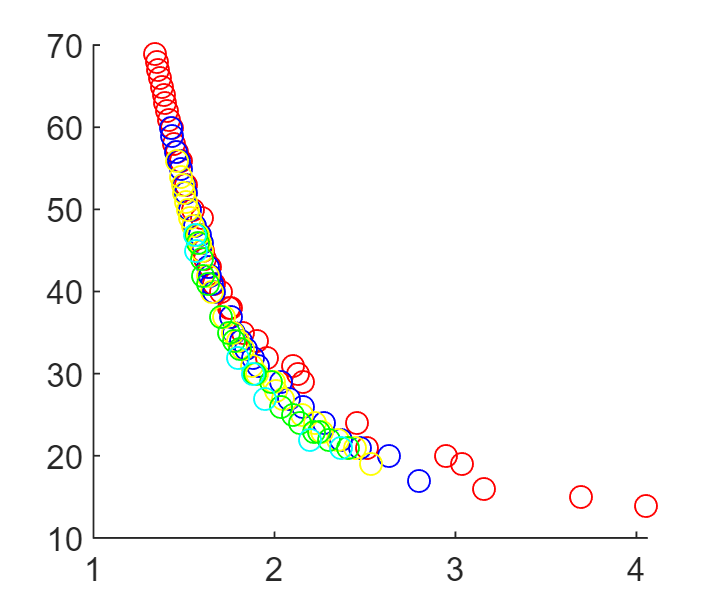

hold on
plot(f1(allFronts(1).front), f3(allFronts(1).front), 'ro');
plot(f1(allFronts(2).front), f3(allFronts(2).front), 'bo');
plot(f1(allFronts(3).front), f3(allFronts(3).front), 'yo');
plot(f1(allFronts(4).front), f3(allFronts(4).front), 'go');
plot(f1(allFronts(5).front), f3(allFronts(5).front), 'co');
hold off

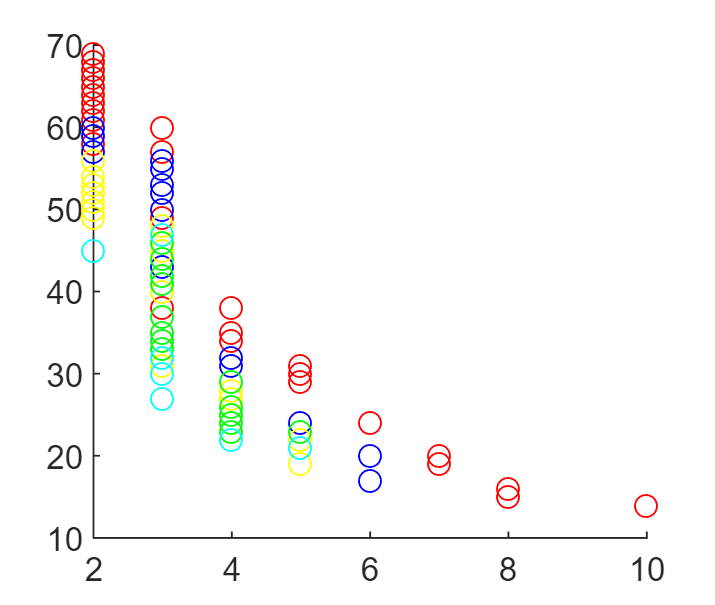

hold on
plot(f2(allFronts(1).front), f3(allFronts(1).front), 'ro');
plot(f2(allFronts(2).front), f3(allFronts(2).front), 'bo');
plot(f2(allFronts(3).front), f3(allFronts(3).front), 'yo');
plot(f2(allFronts(4).front), f3(allFronts(4).front), 'go');
plot(f2(allFronts(5).front), f3(allFronts(5).front), 'co');
hold off

[allFronts, ~] = non_dominated_sorting(graphs);
fitValues = multi_obj_fitness(graphs);
set(gcf,'Position',[100 100 260 220]);
plot(fitValues{1}(allFronts(1).front), fitValues{2}(allFronts(1).front), 'bo');
plot(fitValues{1}(allFronts(2).front), fitValues{2}(allFronts(2).front), 'go');
plot(fitValues{1}(allFronts(3).front), fitValues{2}(allFronts(3).front), 'ko');
plot(fitValues{1}(allFronts(4).front), fitValues{2}(allFronts(4).front), 'ro');

[bestGraph, bestFit] = EA(15, 0.4, 0.4)

bestGraph =      0     0     0     1     0     1     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     1     0     0     0     0     0     0     0     0     0
     0     0     0     0     1     0     0     1     0     0     0     0     0     0     0
     1     0     0     0     0     0     0     0     0     0     1     0     0     0     0
     0     0     1     0     0     0     0     0     0     0     0     0     1     0     0
     1     1     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     1     0     0     0     0     0     0
     0     0     1     0     0     0     0     0     0     0     0     1     0     0     0
     0     0     0     0     0     0     1     0     0     0     0     0     0     1     0
     0     0     0     0     0     0     0     0     0     0     0     1     0     1     0


bestFit = 8.6667

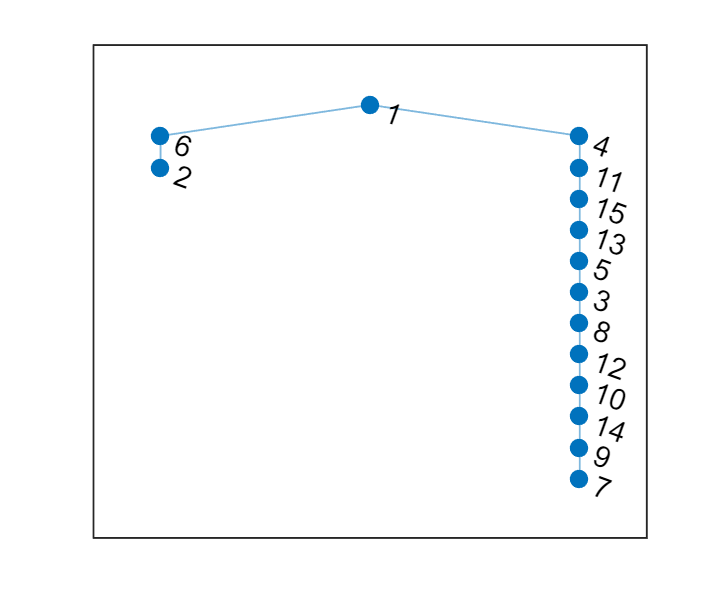

set(gcf,'Position',[100 100 260 220]);
plot(graph(bestGraph))

[bestGraph, bestFw] = EA_weighted_fitness(15, 0.4, 0.4, 20, 5, 5);
cal_avg_path_len(bestGraph)

ans = 2.2000

cal_diameter(bestGraph)

ans = 3

cal_link_num(bestGraph)

ans = 15

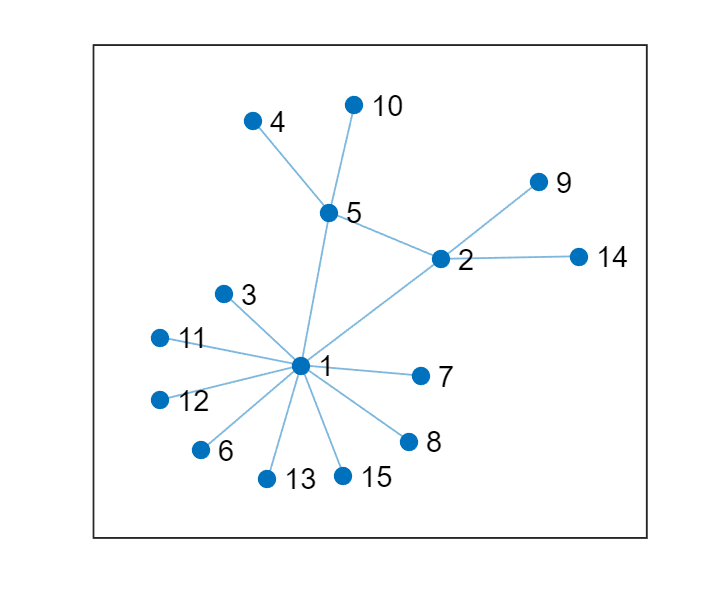

set(gcf,'Position',[100 100 260 220]);
plot(graph(bestGraph))

[bestSolutions, multiFitValues] = MOEA(15, 0.3, 0.3);
f1 = ones(1, 10)./multiFitValues{1};
f2 = ones(1, 10)./multiFitValues{2};
f3 = ones(1, 10)./multiFitValues{3};
[allFronts, ~] = non_dominated_sorting(bestSolutions);
for i = 1 : 10
    fprintf("" + f1(i) + " , " + f2(i) + " , " + f3(i) + "\n");
end

5.3333 , 14 , 14
1 , 1 , 105
5.3333 , 14 , 14
1 , 1 , 105
1.2 , 2 , 84
3.5048 , 8 , 29
1.3714 , 3 , 71
1.0095 , 2 , 104
3 , 6 , 32
1.6762 , 4 , 53


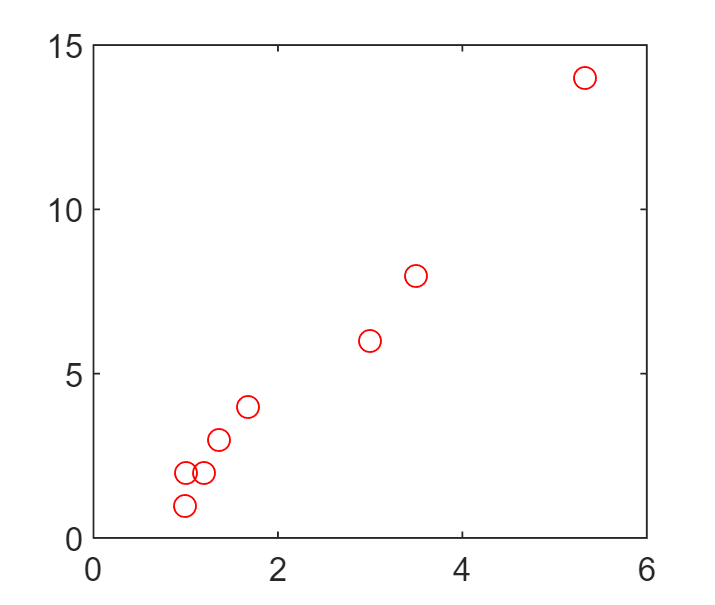

set(gcf,'Position',[100 100 260 220]);
plot(f1(1 : 10), f2(1 : 10), 'ro');

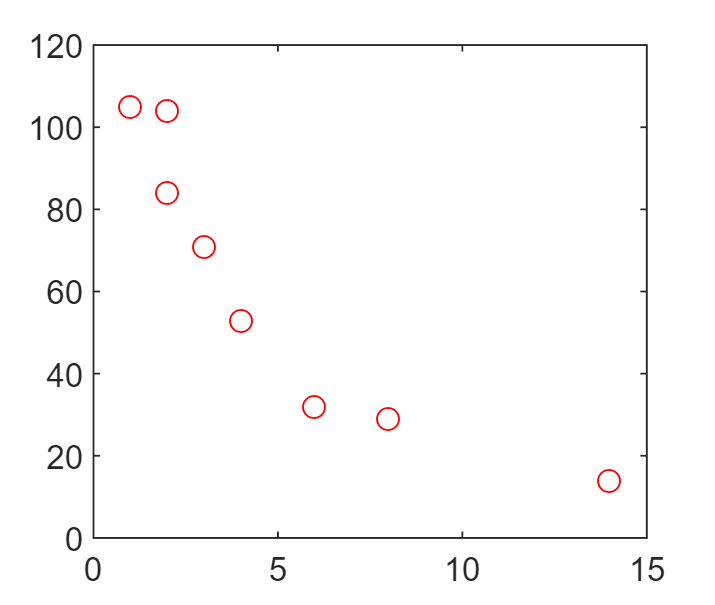

plot(f2(1 : 10), f3(1 : 10), 'ro');

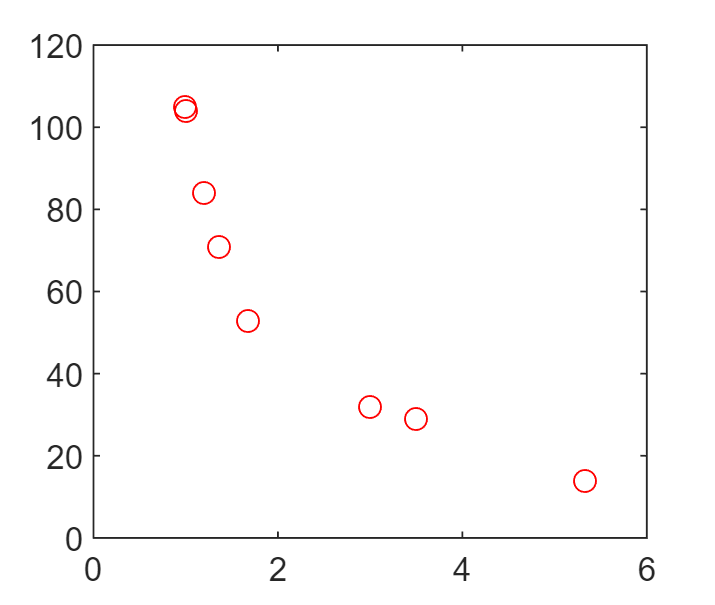

plot(f1(1 : 10), f3(1 : 10), 'ro');

plot(graph(bestSolutions{1}))

[~] = non_dominated_sorting(graphs);
offGraphs = mutation(graphs, 0.3, 0.2);
comPop = [graphs, offGraphs];

[allFronts, ~] = non_dominated_sorting(comPop)
crowDists = crowding_distance(comPop, allFronts)
newPop = elite_preservation(comPop, 100, allFronts, crowDists)
[allFronts, popRank] = non_dominated_sorting(newPop)
multiFitValues = multi_obj_fitness(newPop);

bestGraph = EA(15, 0.3, 0.3);
fprintf("" + (cal_diameter(bestGraph) - cal_avg_path_len(bestGraph)) + "\n");

cal_avg_path_len([0, 1, 0, 1; 1, 0, 1, 0; 0, 1, 0, 1; 1, 0, 1, 0])

[bestSolutions, bestMultiFitValues] = MOEA(15, 0.3, 0.3);
f1 = ones(1, 100)./bestMultiFitValues{1}
f2 = ones(1, 100)./bestMultiFitValues{2}
f3 = ones(1, 100)./ bestMultiFitValues{3}

plot(f1(1:10), f2(1:10), "b-o");